### **Chapter 5: I only deploy on Fridays**

We are now fully fledged contributors to this toolbox. Now let's get to the money maker. The task at hand is for you to not only distrubute this as a toolbox, which we have now show can be done consistently, but your company is not hosting a shiny new MATLAB Production Server, and you need to take the main entry point of this toolbox and expose it as a service. 

We have already done the development work here. It involves creating:

- Creating some Production Server Options

showCode("build/generateMPSOptions.m")

- A FunctionSignatures.json file

showCode("build/simulateSystemFunctionSignatures.json")

- ...and a new `ctf `task that we can add to the build

showCode("buildfile.m","131:141")
showCode("buildfile.m","64:71")

However, in addition to the code needed to build the archive, we also want to keep up the quality we've come to expect. We can also leverage equivalence tests to ensure that the code running on the server is equivalent to the proven code. Running on a production server is a different environment than a local MATLAB instance. With a service comes reliability requirements, and it is important to ensure there is some level of integration coverage for the service as well. To see this we have included a parameterized equivalence test that takes the resulting CTF archive that we built and injects a variety of data to confirm that the service is behaving equivalently to the MATLAB source.

showCode("integTests/equivalence/MPSEquivalenceTest.m")

We add a new integration test task to the build, along with a new deploy task:

showCode("buildfile.m","73:80")

Now that we've implemented the production server archive build, written equivalence tests against it, and added these tasks to our build. All we need to do now is adjust the default tasks in the build to include the deployment step

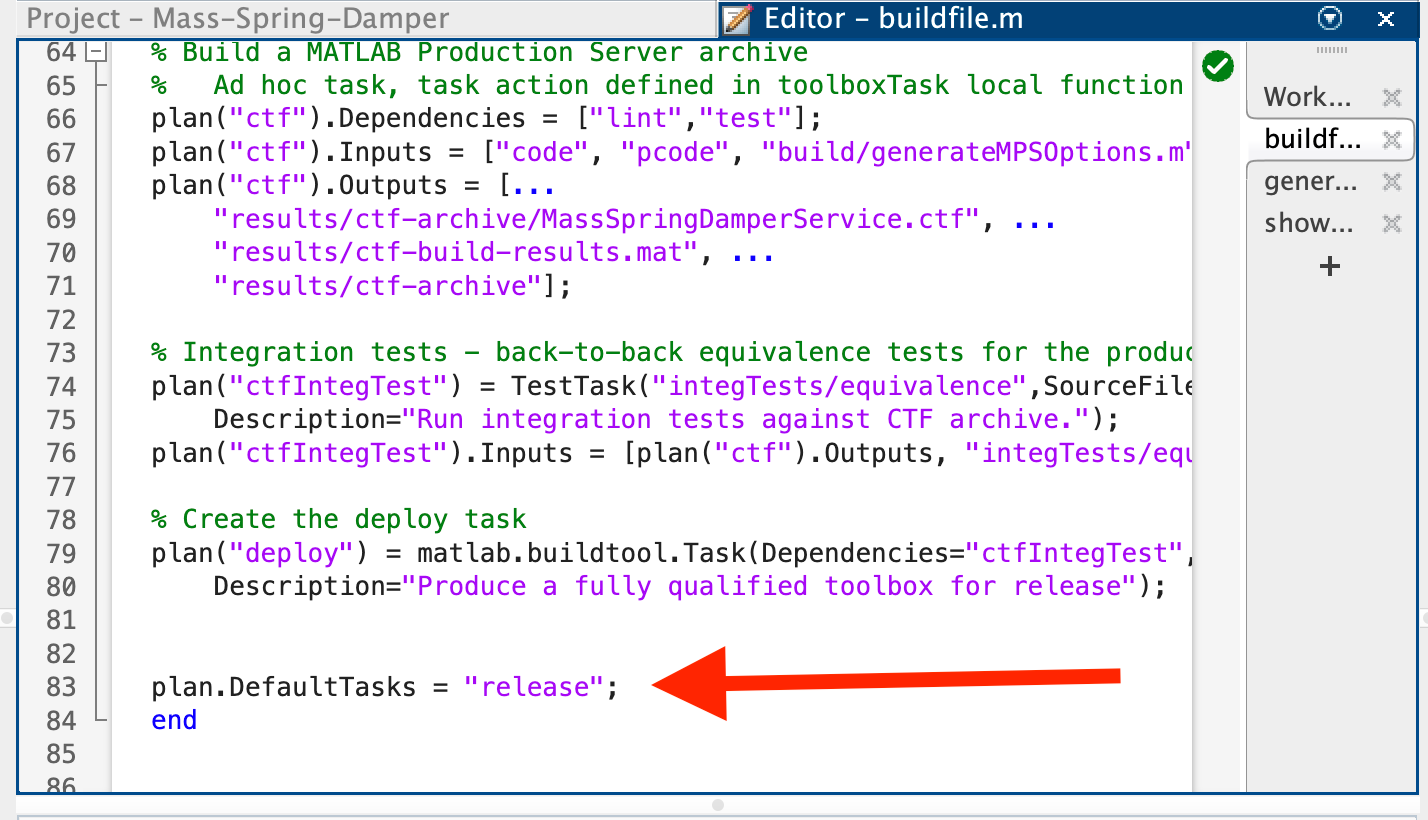

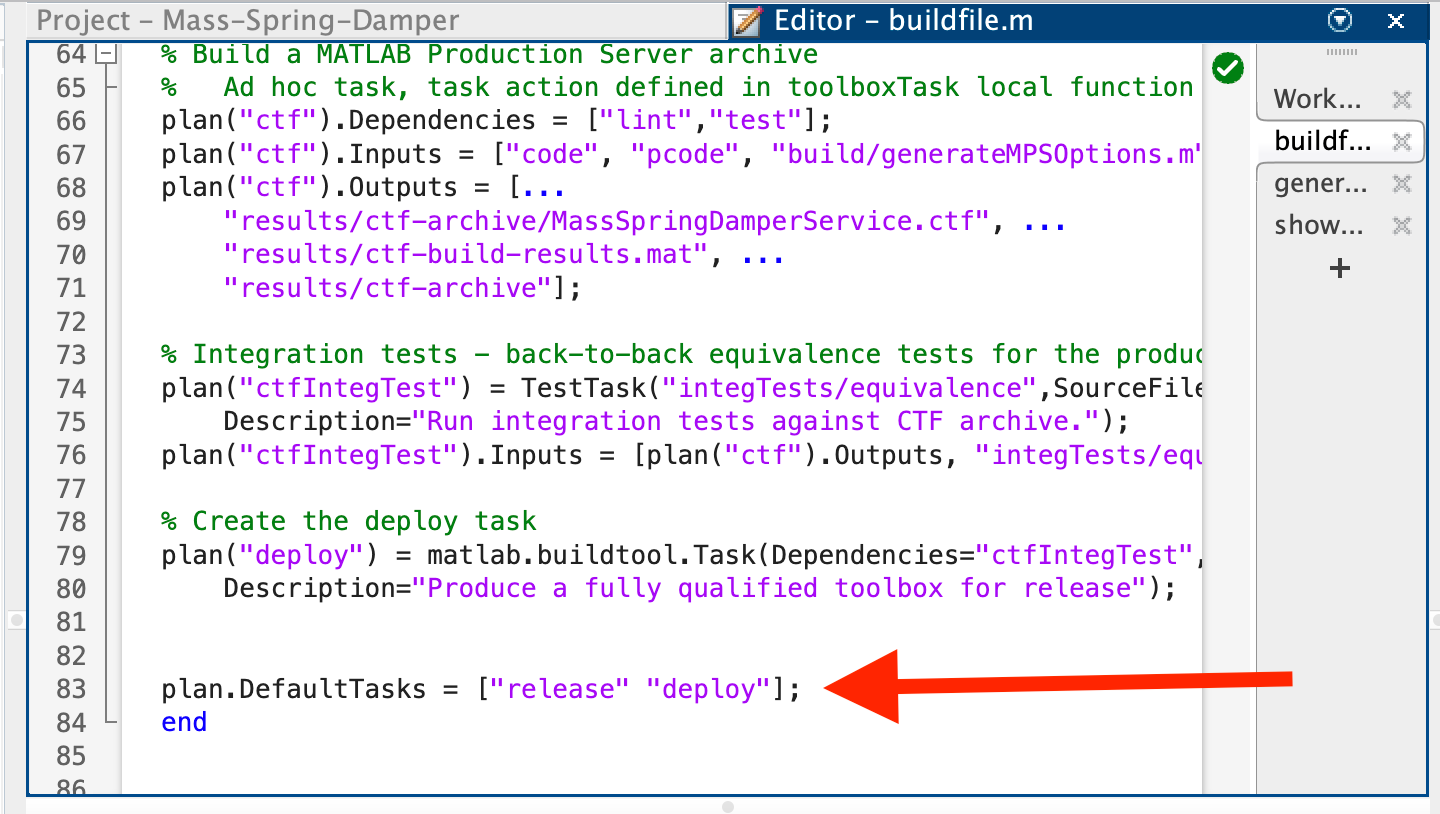

opentoline("buildfile.m",83)

Development tools for the win! Now just build it to confirm it is all working locally before submitting.

Good to go. Now commit, add a message, and push!

open Chapter_6

#### [Preface & TOC](matlab:open('index.html')) | [Chapter 6](matlab:open('Chapter_6.html'))